clc;clear au;close all;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


gp=(-3*s+1)/(5*s+1) %gp=G

gp =
 
  -3 s + 1
  --------
  5 s + 1
 
Continuous-time transfer function.
Model Properties


INV = (3*s+1)\(5*s+1)

INV =
 
  5 s + 1
  -------
  3 s + 1
 
Continuous-time transfer function.
Model Properties



Lambda1 = 10;
Lambda2 = 0.1;

F = 1/(Lambda2*s+1)

F =
 
      1
  ---------
  0.1 s + 1
 
Continuous-time transfer function.
Model Properties


C = INV*F

C =
 
        5 s + 1
  -------------------
  0.3 s^2 + 3.1 s + 1
 
Continuous-time transfer function.
Model Properties


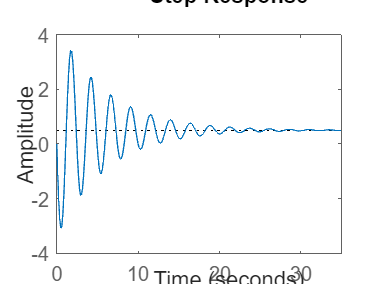

step(feedback(gp*C,1))

clc;clear au;close all;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


gp=10*(-3*s+7)/(5*s+1) %gp=G

gp =
 
  -30 s + 70
  ----------
   5 s + 1
 
Continuous-time transfer function.
Model Properties


INV = (3*s+7)\(5*s+1)

INV =
 
  5 s + 1
  -------
  3 s + 7
 
Continuous-time transfer function.
Model Properties


INV = INV/(dcgain(INV)*dcgain(gp)) %---> elimina error en estado estacionario

INV =
 
   5 s + 1
  ---------
  30 s + 70
 
Continuous-time transfer function.
Model Properties


Lambda1 = 2;
Lambda2 = 0.8;

F = 1/(Lambda2*s+1)

F =
 
      1
  ---------
  0.8 s + 1
 
Continuous-time transfer function.
Model Properties


C = INV*F

C =
 
       5 s + 1
  ------------------
  24 s^2 + 86 s + 70
 
Continuous-time transfer function.
Model Properties


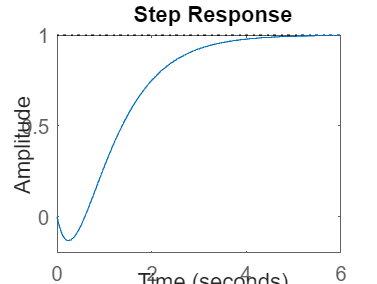

step(gp*C)

clc;clear au;close all;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


gp=10*(-3*s+7)/(5*s+1) %gp=G

gp =
 
  -30 s + 70
  ----------
   5 s + 1
 
Continuous-time transfer function.
Model Properties


INV = (3*s+7)\(5*s+1)

INV =
 
  5 s + 1
  -------
  3 s + 7
 
Continuous-time transfer function.
Model Properties


INV = INV/(dcgain(INV)*dcgain(gp)) %---> elimina error en estado estacionario

INV =
 
   5 s + 1
  ---------
  30 s + 70
 
Continuous-time transfer function.
Model Properties


Lambda1 = 2;
Lambda2 = 0.8;
n = 4;
gamma = 0.01;
F = (gamma*s+1)/(Lambda2*s+1)^n

F =
 
                   0.01 s + 1
  ---------------------------------------------
  0.4096 s^4 + 2.048 s^3 + 3.84 s^2 + 3.2 s + 1
 
Continuous-time transfer function.
Model Properties


C = INV*F

C =
 
                    0.05 s^2 + 5.01 s + 1
  ----------------------------------------------------------
  12.29 s^5 + 90.11 s^4 + 258.6 s^3 + 364.8 s^2 + 254 s + 70
 
Continuous-time transfer function.
Model Properties


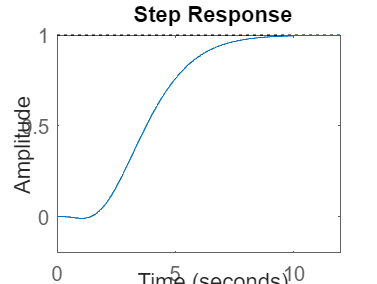

step(gp*C)